% Define simulation parameters
T = 5;
dt = 0.01;
t = 0:dt:T;

% Define vehicle properties
m = 1.0;
g = 9.81;
r = 0.1;
I = 0.1;
u1 = 5.0;
u2 = 5.01;

f = @(x_sym) [
    x_sym(2);
    -(u1 + u2) * sin(x_sym(5)) / m;
    x_sym(4);
    (u1 + u2) * cos(x_sym(5)) / m - g;
    x_sym(6);
    r * (u1 - u2) / I
];

g = @(x_sym) [
    x_sym(2);
    -(u1 + u2) * sin(x_sym(5)) / (2*m);
    x_sym(4);
    (u1 + u2) * cos(x_sym(5)) / (2*m) - g;
    x_sym(6);
    r * (u1 - u2) / I
];

x0 = [0; 0; 0; 0; 0; 0]; 
z0 = [0; 0.1; 0; 0.1; 0; 0];

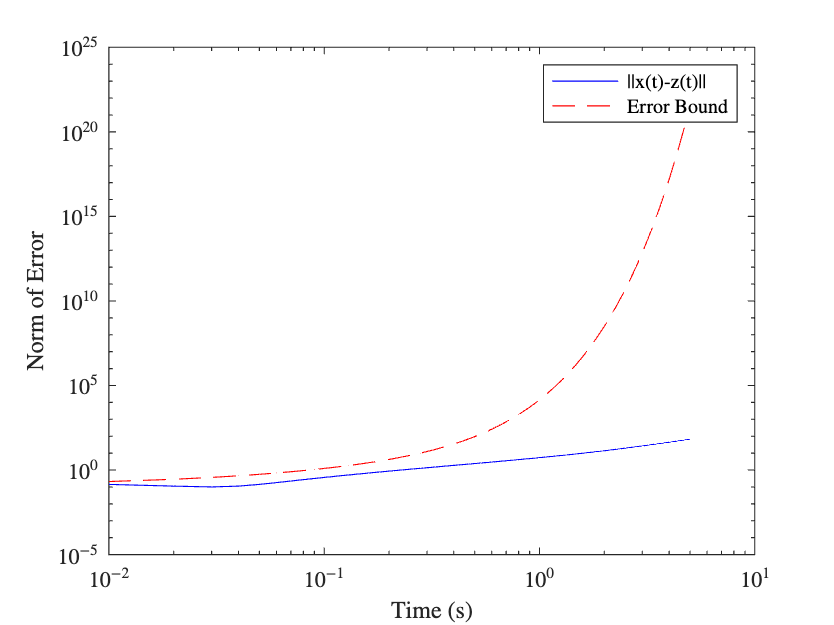

[t_x,x] = ode45(@(t,x) f(x), [0 t], x0);

[t_z,z] = ode45(@(t,z) g(z), [0 t], z0);


L = (u1 + u2)/m;
mu = (u1 + u2)/(2*m);
delta_0 = norm(x0 - z0);

actual_error = arrayfun(@(i) norm(x(i,:) - z(i,:)), 1:length(t));
bound = delta_0*exp(L*t) + (mu/L)*(exp(L*t) - 1); % This is the integral form of 3.15

figure
loglog(t, actual_error, 'b')
hold on
loglog(t, bound, 'r--')
xlabel('Time (s)')
ylabel('Norm of Error')
legend('||x(t)-z(t)||', 'Error Bound')

title('Demonstration')